# Exam 2015

## Problem 1: Estimate PSD of signal using Pisarenko

The autocorrelation function of an unknown signal is estimated as

          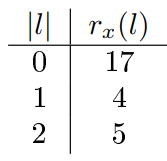

clear variables;

### [✔] 1) Estimate and sketch the PSD of sinusoidal signal in white noise

The Pisarenko method can be used to recover the sinusoidal frequencies of a corrupted signal $x\left(n\right)$ given two assumptions:

- The signal $x\left(n\right)$ consists of $p$ sinusoids that has been corrupted by white noise.

- The autocorrelation matrix of size $\left(p+1\right)\times \left(p+1\right)$ is known or can be estimated from data

The Pisarenko method consists of the following steps:

***Step 1***: Compute the autocorrelation matrix ${\mathbf{R}}_{\mathrm{xx}}$

***Step 2:*** Find the eigenvector corresponding to the smallest minimum eigenvalue. The elements of this eigenvector is the parameters of the $\mathrm{ARMA}\left(2p,2p\right)$ model 

***Step 3:*** Find the frequencies $\left\lbrace \;f_i \;\right\rbrace$ of the sinusoids. This can be done by computing the roots of the polynomial $A\left(z\right)$ in Eq. (14.5.4) in the book. This polynomial has $2p$ poles on the unit circle which correspond to the frequencies of the system.

        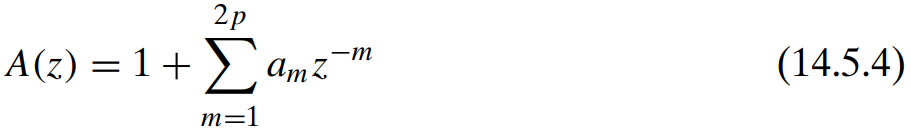

***Step 4*****:** Solve Eq. (14.5.11) for the signal powers $\left\lbrace P_i \right\rbrace$

        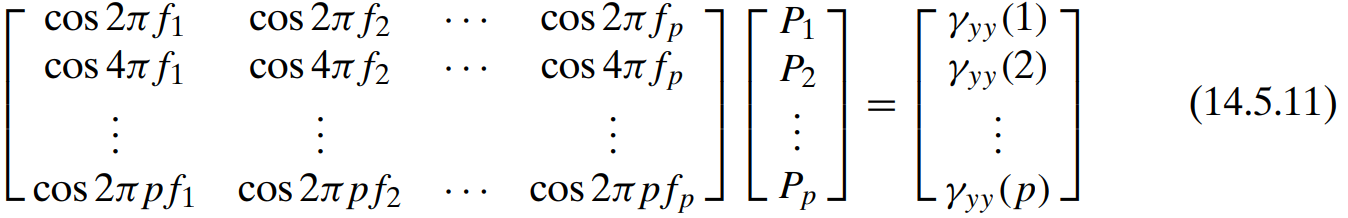

where 

- $\gamma_{\mathrm{yy}} \left(1\right),\gamma_{\mathrm{yy}} \left(2\right),\cdots ,\gamma_{\mathrm{yy}} \left(p\right)$ are the estimated autocorrelation values 

- $P_i =\frac{A_i^2 }{2}$ is the average power of the $i$th sinusoid and $A_i$ is the corresponding amplitude

***Step 5***: Estimate the amplitude $A_i =\sqrt{2P_i }$

These steps are coded up in the `pisarenko()` function (see at end of this document):

These steps are coded up in the `pisarenko()` function (see at end of this document):

r_xx = [17, 4, 3]; % In the solution r_x(2)=3
[F, A, P, lambda_min] = pisarenko(r_xx, 1)

F = 0.0645

A = 2.9504

P = 4.3523

lambda_min = 12.6477

We can describe the signal as:

        
$$x\left(n\right)=2\ldotp 8284j\;\cos \left(\pi n\right)+w\left(n\right)$$


where $w\left(n\right)$ is white noise with variance $\sigma_w^2 =12$

To compute the power spectral density, we need to find the autocorrelation function of the sinusoid.

In ADSI Problem 4.4, we found that the autocorrelation of a real sinusoid given by $y\left(n\right)=A\;\mathrm{cos}\left(\omega n+\phi \right)$ where $A$ and $\omega$ are real constants and $\phi$ is a random variable with $\phi ~U\left(0,2\pi \right)$ is:

        
$$r_{\textrm{yy}} \left(\ell \right)=\frac{A^2 }{2}\mathrm{cos}\left(\omega \ell \right)$$


The autocorrelation function of white noise with variance $\sigma_w^2$ is given by:

        
$$r_{\mathrm{ww}} \left(\ell \right)=\sigma_w^2 \delta \left(\ell \right)$$


Combining these results, the general autocorrelation function of our signal is:

        
$$r_{\mathrm{xx}} \left(\ell \right)=\frac{A^2 }{2}\mathrm{cos}\left(\omega \ell \right)+\sigma_w^2 \delta \left(\ell \right)$$


The power spectral density is the Fourier transform the autocorrelation function which is given by:

        
$$S\left(\omega \right)=\frac{A^2 }{2}\pi \left\lbrack \delta \left(\omega -\omega_0 \right)+\delta \left(\omega +\omega_0 \right)\right\rbrack +\sigma_w^2$$


A, F, lambda_min

A = 2.9504

F = 0.0645

lambda_min = 12.6477

Using the values found via the Pisarenko, the PSD is:

        
$$S\left(\omega \right)=\frac{{\left(2\ldotp 9504\right)}^2 }{2}\pi \left\lbrack \delta \left(\omega -0\ldotp 0645\cdot 2\pi \right)+\delta \left(\omega +0\ldotp 0645\cdot 2\pi \right)\right\rbrack +12\ldotp 6477$$


We can plot the PSD:

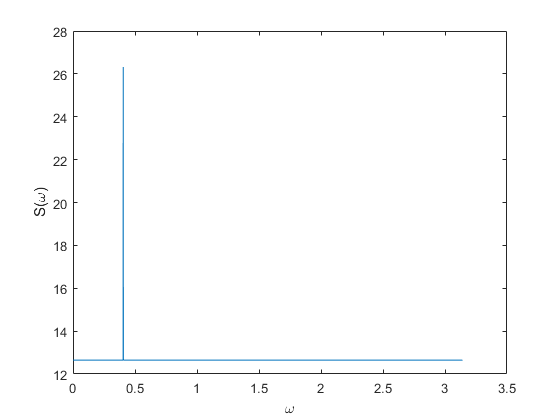

D = 3;
w = 0:10^(-D):pi;
delta = @(n) round(n, D) == 0;
S = (A^2/2)*pi * (delta(w-(F*2*pi)) + delta(w+(F*2*pi))) + lambda_min;
%plot(w/pi, real(pow2db(S)))
plot(w, S); 
xlabel('\omega')
ylabel('S(\omega)')

### [✔] 2) Calculate the signal to noise ratio

The signal to noise ratio is the power of the signal divided by the power of the noise:

        
$$\mathrm{SNR}=\frac{\mathrm{power}\;\mathrm{of}\;\mathrm{signal}}{\textrm{power}\;\textrm{of}\;\textrm{noise}}=\frac{P}{\sigma_w^2 }=0\ldotp 3441$$


SNR = P/lambda_min

SNR = 0.3441

### [✔] 3) Does an additional value to the ACRS agree with the signal model?

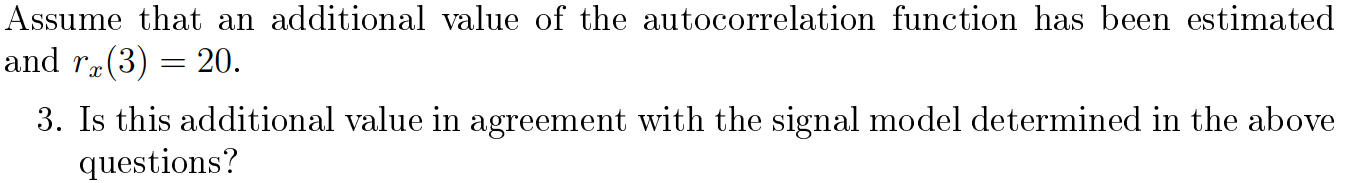

The additional autocorrelation value is not in agreement with the signal model.

A fundamental property of the autocorrelation function is that $r_x \left(0\right)\ge r_x \left(\ell \right)$ for all $\ell$. 

This property is voilated with $r_x \left(0\right)=17$ and $r_x \left(3\right)=20$.

## Problem 2: Allpass filters

Let a system function be given by:

        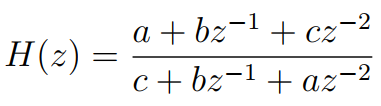

where *a*, *b *and *c *are non-zero numbers.

### [✔] 1) Show that the system function H(z) is an allpass filter

An $N$-order allpass systems is given by  

        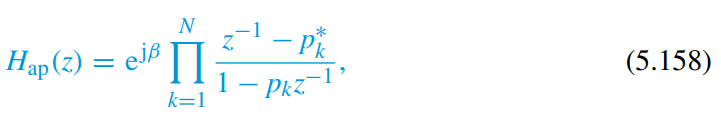  

where *β *is a constant (usually *β *= 0).

A second-order allpass system function can be expressed as:

        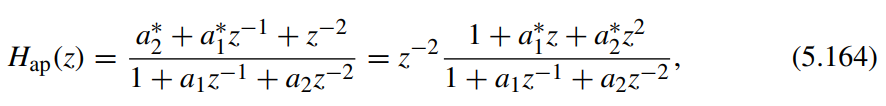

We can show that the given system function is an allpass filter if we can express it as in Eq. (5.164).

Since we want the denominator to contain a single 1 term, we scale both numerator and denominator by $\frac{1}{c}$:

        
$$H\left(z\right)=\frac{a+bz^{-1} +cz^{-2} }{c+bz^{-1} +az^{-2} }$$


        
$$H\left(z\right)=\frac{\frac{1}{c}\left(a+bz^{-1} +cz^{-2} \right)}{\frac{1}{c}\left(c+bz^{-1} +az^{-2} \right)}$$


        
$$H\left(z\right)=\frac{\frac{a}{c}+\frac{b}{c}z^{-1} +\frac{c}{c}z^{-2} }{\frac{c}{c}+\frac{b}{c}z^{-1} +\frac{a}{c}z^{-2} }$$


        
$$H\left(z\right)=\frac{\frac{a}{c}+\frac{b}{c}z^{-1} +z^{-2} }{1+\frac{b}{c}z^{-1} +\frac{a}{c}z^{-2} }$$


### [?] 2) Realise an allpass filter as an all-pole lattice filter

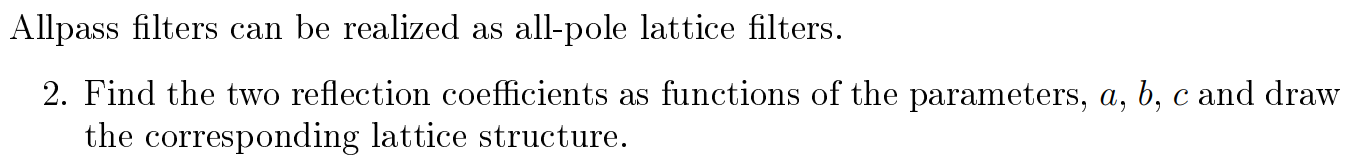

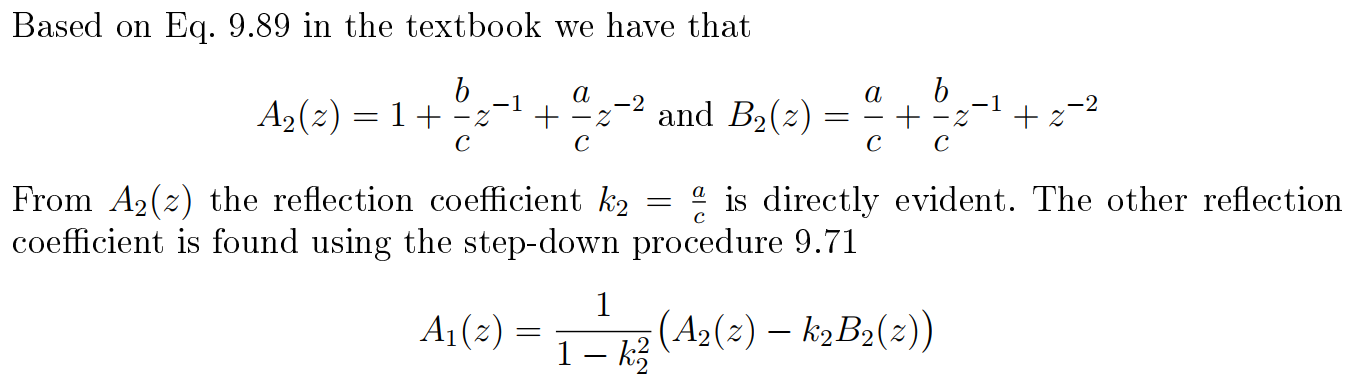

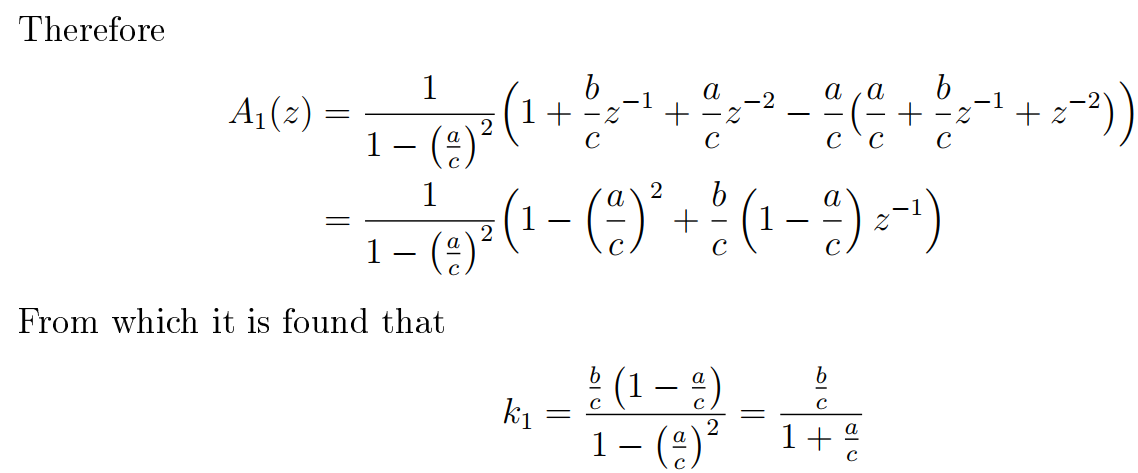

The corresponding lattice structure is

          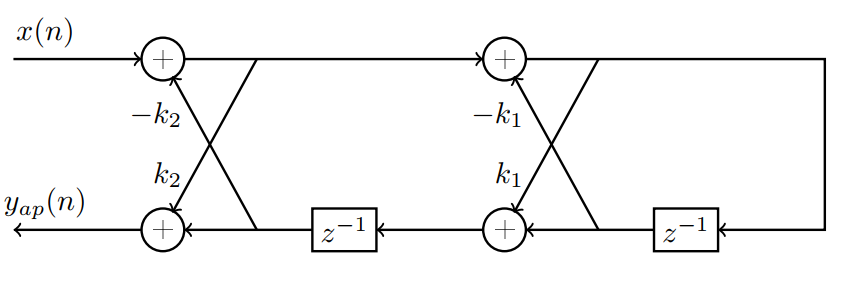

## Problem 3: Recover signal by a Wiener filter

clear variables;

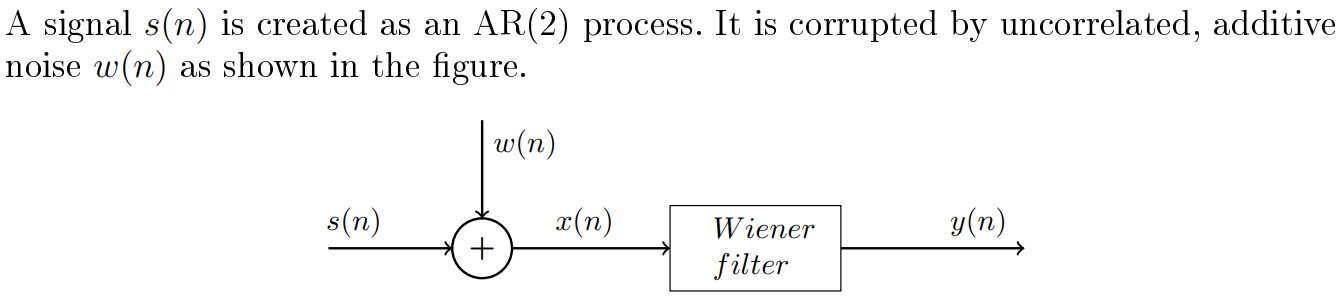

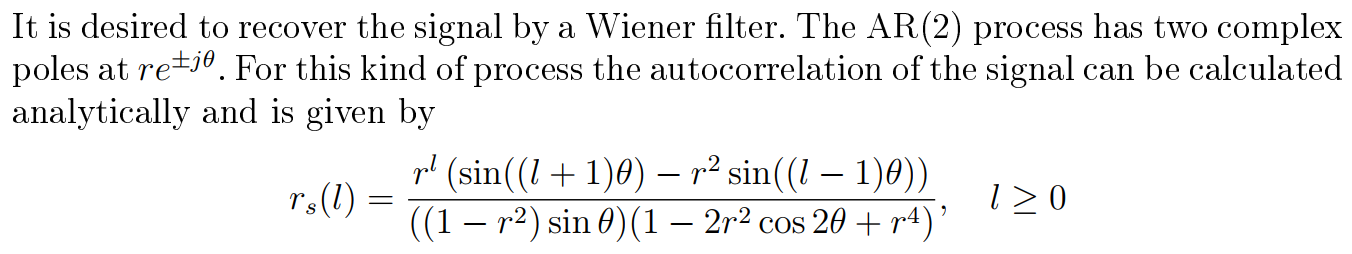

For simplicity the first few values of the autocorrelation function for this specific process is given by  

        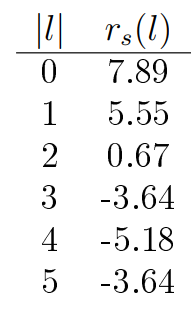

r_ss = [7.89, 5.55, 0.67, -3.64, -5.18, -3.64];

Less information is known about the noise. The autocorrelation for the first few lags are given by:

          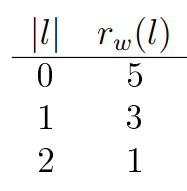

For all other lags, the autocorrelation, $r_w \left(l\right)$ is assumed to be zero.

r_ww = [5, 3, 1, 0, 0, 0];

### [✔] 1) Design a 4 tap Wiener filter to recover *s*(*n*).

The $p$-order Wiener filter for estimating the signal $s\left(n\right)$ is given by:

        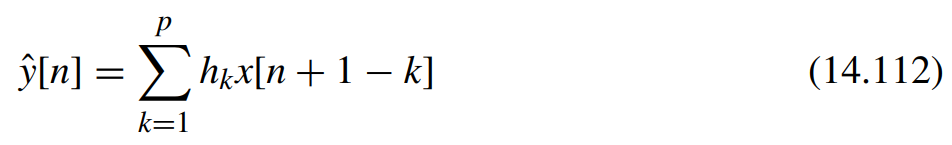

The optimum Wiener filter coefficients is given by the Wiener-Hopf equation:

        

where ${\mathit{\mathbf{R}}}_x$ is the autocorrelation matrix of the corrupted signal $s\left(n\right)$ and $\mathit{\mathbf{g}}$ is the cross-correlation between the desired signal $s\left(n\right)$ and the corrupted signal $x\left(n\right)$.

Designing a Wiener filter to recover a corrupted signal involves 3 steps:

- Compute the autocorrelation sequence $r_x \left(\ell \right)$ and matrix $R_x$

- Compute the cross-correlation $r_{\mathrm{sx}} \left(\ell \right)$

- Solve the Wiener-Hopf equation to find the optimum Wiener filter coefficients

**Step 1: **Compute the autocorrelation $r_x \left(\ell \right)$:

Since the signal $s\left(n\right)$ and the noise $w\left(n\right)$ are uncorrelated the autocorrelation function of $s\left(n\right)$ is just the sum of the individual autocorrelation functions:

        
$$rx\left(\ell \right)=E\left\lbrack x\left(n\right)x\left(n-\ell \right)\right\rbrack$$


                 
$$=E\left\lbrack \left(s\left(n\right)+w\left(n\right)\right)\left(s\left(n-\ell \right)+w\left(n-\ell \right)\right)\right\rbrack$$


                 
$$=E\left\lbrack s\left(n\right)s\left(n-\ell \right)+s\left(n\right)w\left(n-\ell \right)+w\left(n\right)s\left(n-\ell \right)+w\left(n\right)w\left(n-\ell \right)\right\rbrack$$


                 
$$=r_s \left(\ell \right)+r_{\textrm{sw}} \left(\ell \right)+r_{\textrm{sw}} \left(\ell \right)+r_w \left(\ell \right)$$


                 $=r_s \left(\ell \right)+r_w \left(\ell \right)$ (assuming $s\left(n\right)$ and $w\left(n\right)$ are uncorrelated)

p = 4;
r_xx = r_ss + r_ww;
R_xx = toeplitz(r_xx(1:p))

**Step 2:** Compute the cross-correlation $r_{\mathrm{sx}} \left(\ell \right)$:

Since the desired signal is $s\left(n\right)$, the cross-correlation between $s\left(n\right)$ and $s\left(n\right)$ simplifies to the autocorrelation of the signal $r_s \left(\ell \right)$:

        
$$r_{\textrm{sx}} \left(\ell \right)=E\left\lbrack s\left(n\right)x\left(n-\ell \right)\right\rbrack$$


                 
$$=E\left\lbrack s\left(n\right)\left(s\left(n-\ell \right)+w\left(n-\ell \right)\right)\right\rbrack$$


                 
$$=E\left\lbrack s\left(n\right)s\left(n-\ell \right)+s\left(n\right)w\left(n-\ell \right)\right\rbrack$$


                 
$$=r_s \left(\ell \right)+r_{\mathrm{sw}} \left(\ell \right)$$


                 $=r_s \left(\ell \right)$   (assuming $s\left(n\right)$ and $w\left(n\right)$ are uncorrelated)

g = r_ss(1:p)'

**Step 3:** Compute the optimum filter coefficients:

h_opt = R_xx\g

### [✔] 2) Calculate the minimum mean square error (MSE)

The minimum value of the mean square error $E\left\lbrack e^2 \left(n\right)\right\rbrack E\left\lbrack {\left(y\left(n\right)-\hat{y} \left(n\right)\right)}^2 \right\rbrack$ is given by  

        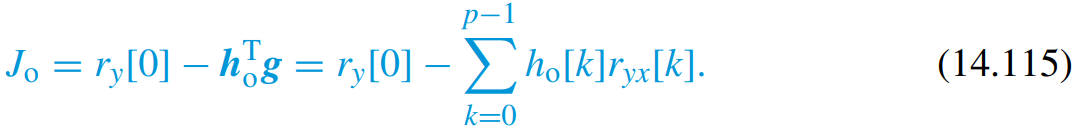

mse = r_ss(1) - h_opt'*g

R_xx =    12.8900    8.5500    1.6700   -3.6400
    8.5500   12.8900    8.5500    1.6700
    1.6700    8.5500   12.8900    8.5500
   -3.6400    1.6700    8.5500   12.8900


### [✔] 3) Can the MSE be lowered using a longer Wiener filter?

*Explain whether the minimum mean square error can be lowered by using a longer Wiener filter when we only have sparse knowledge of the noise. *

The minimum mean square error can be reduced further by increasing the length of the Wiener filter. As the length of the fiter is increased the frequency resolution increases and the spectral shape of the filter becomes better suited for passing the signal and rejecting the noise. 

This is also evident if the minimum mean square error is calculated. For a 5 tap filter, the minimum mean square error decreases to 2.6617:

p = 5;

g =     7.8900
    5.5500
    0.6700
   -3.6400


r_xx = r_ss + r_ww;
R_xx = toeplitz(r_xx(1:p));
g = r_ss(1:p)';

h_opt =     0.4841
    0.1026
    0.0477
   -0.1906


h_opt = R_xx\g;
mse = r_ss(1) - h_opt'*g

## Problem 4: True/False

### 1) A serial connection of two all-pass filters is also an all-pass filter.

Answer: TRUE

The transfer function of a serial connection of two fiters is just the individual transfer functions multiplied. For the magnitude part this becomes:

        

## Functions

function [F, A, P, lambda_min]=pisarenko(r_xx, p)

mse = 2.7757

    % Estimates the frequencies and amplitudes using the Pisarenko method
    %  r_xx: autocorrelation sequence starting from zero. 
    %        The length of ACRS must be at least 2p+1.
    %  p: assumed number of sinusoids in the signal
    %  F: normalised frequencies of the sinuoids
    %  A: amplitudes of the sinuoids
    if numel(r_xx) < 2*p+1
        error(strcat('The length of ACRS must be at least ', int2str(2*p+1)));
    end
    
    % Compute the autocorrelation matrix

mse = 2.6617

    R_xx = toeplitz(r_xx(1:2*p+1));
    
    % Perform the eigendecomposition
    [eigvecs, eigvals] = eigs(R_xx, size(R_xx, 1), 'smallestreal');
    
    eigvals = diag(eigvals);
    lambda_min = eigvals(1);
    
    % Find the eigenvector 'a' corresponding to the smallest eigenvalue.
    % The function eigs() sorts eigenvectors, so just pick the first column.
    a = eigvecs(:, 1);
    
    % Ensure that a_0 = 1 (this is by definition)
    a = a / a(1);
    
    % The elements of this eigenvector corresponds to the parameters
    % of an ARMA(2p, 2p) model: a_0, a_1, ..., a_2p where p: number of sinusoids
    % The polynomial A(z) in (14.5.4) has 2p poles on the unit circle.
    % Obtain the poles by finding the roots of the system.
    z = roots(a);
    
    % Estimate frequencies
    F = zeros(p, 1);
    for i = 1:p
        % The poles come in pairs. Each pair is complex conjugate
        % of one another. Only use one of them and find the absolute value.
        z_i = z(2*i);
        F(i) = abs(angle(z_i)) / (2*pi);
    end
    
    % Build the matrix of cosines
    C = zeros(p);
    for i = 1:p
        for j = 1:p
            C(i, j) = cos(i * 2*pi * F(j));
        end
    end
    
    % Start the ACRS from the second element according to equation (14.5.11)
    gamma = r_xx(2:p+1);
    
    % Solve equation (14.5.11) for P
    P = C\gamma; % Same as `inv(C)*gamma` but faster and more accurate
    
    % Since P=A^2/2, we can compute the amplitude A=sqrt(2*P)
    A = sqrt(2 * P);
end

